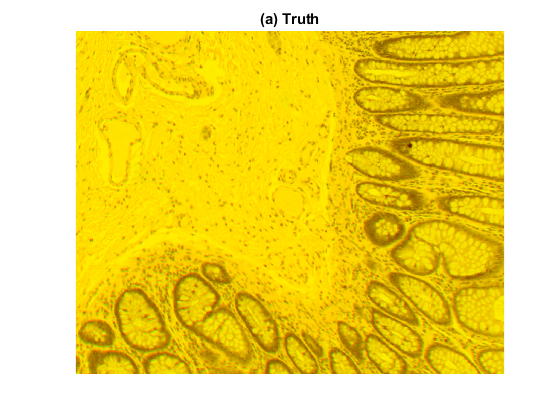

clear

load('output_images','original','unregistered','registered_cp','registered_cp_corr','imf_before','imf_cp_corr')

% parameter offset
offsetx = 0;
offsety = 0;

% get original size
sizex1 = 1;
sizey1 = 1;
sizex2 = size(original,2);
sizey2 = size(original,1);

% reduce the size by offset
sizex1 = sizex1 + abs(offsetx);
sizex2 = sizex2 - abs(offsetx);

sizey1 = sizey1 + abs(offsety);
sizey2 = sizey2 - abs(offsety);

imf_test = imfuse(original(sizey1:sizey2,sizex1:sizex2),registered_cp_corr([sizey1:sizey2]+offsety,[sizex1:sizex2]+offsetx),'falsecolor','Scaling','joint','ColorChannels',[1 2 0]);

image(imf_test);
title('(a) Truth')
axis image
axis off